m_c = 1.5;
m_p = 0.5;
g = 9.82;
L = 1;
d_1 = 0.01;
d_2 = 0.01;
A = [0 0 1 0; 0 0 0 1];
A(3,1) = 0;
A(3,2) = g*m_p/m_c;
A(3,3) = -d_1/m_c;
A(3,4) = -d_2/(L*m_c);
A(4,1) = 0;
A(4,2) = g*(m_p+m_c)/(L*m_c);
A(4,3) = -d_1/(L*m_c);
A(4,4) = (-d_2*(m_c+m_p))/(L*L*m_c*m_p);

B = [0; 0; 1/m_c; 1/(L*m_c)];

C = [0 1 0 0]

C =      0     1     0     0



D = [0];

sys = ss(A,B,C,D)

sys =
 
  A = 
              x1         x2
   x1          0          0
   x2          0          0
   x3          0      3.273
   x4          0      13.09
 
              x3         x4
   x1          1          0
   x2          0          1
   x3  -0.006667  -0.006667
   x4  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



p = pole(sys)

p =    -3.6327
    3.6043
   -0.0050
         0


s = isstable(sys)

s = logical
   0


e = eig(sys)

e =    -3.6327
    3.6043
   -0.0050
         0


z = zero(sys)

z = 	1.0e+-18 *

    0.1016
         0


st = step(sys)

st = 	1.0e+23 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


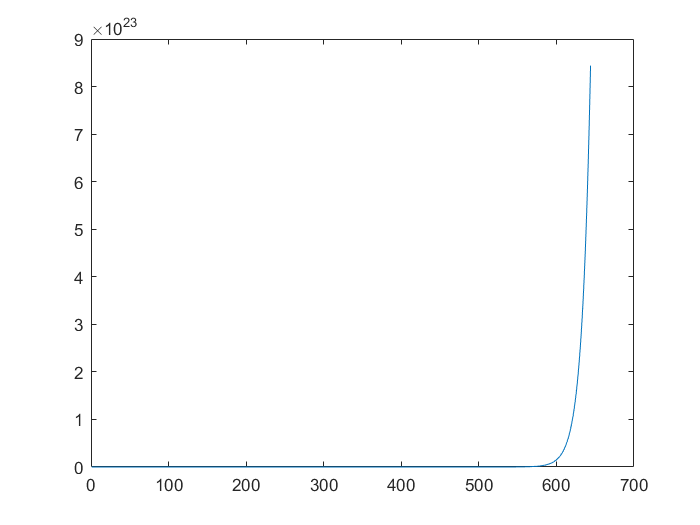

t = 1:1:644;
plot(t,st);

ctrb_matrix = ctrb(sys)

ctrb_matrix =          0    0.6667   -0.0089    2.1824
         0    0.6667   -0.0222    8.7295
    0.6667   -0.0089    2.1824   -0.1455
    0.6667   -0.0222    8.7295   -0.5383


rank(ctrb_matrix)

ans = 4

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=C*(inv(s*eye(4)-A))*B

G =
 
                                
  0.6667 s^4 + 0.02222 s^3      
                                
          - 8.729 s^2           
                                
          - 0.04364 s           
                                
                     - 9.281e-17
                                
  ------------------------------
                                
  s^6 + 0.06667 s^5 - 26.19 s^4 
                                
          - 1.004 s^3           
                                
          + 171.4 s^2           
                                
            + 1.714 s + 0.004286
                                
 
Continuous-time transfer function.



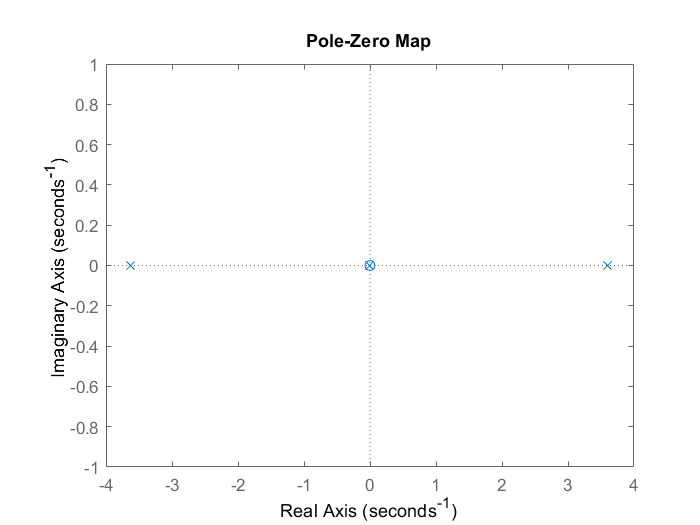

pzmap(sys)


G1=ss2tf(A,B,C,D)

G1 =          0         0    0.6667   -0.0000    0.0000


sys2=zpk(sys)

sys2 =
 
            0.66667 s
  -----------------------------
  (s+3.633) (s-3.604) (s+0.005)
 
Continuous-time zero/pole/gain model.



p

p =    -3.6327
    3.6043
   -0.0050
         0


z

z = 	1.0e+-18 *

    0.1016
         0


G

G =
 
                                
  0.6667 s^4 + 0.02222 s^3      
                                
          - 8.729 s^2           
                                
          - 0.04364 s           
                                
                     - 9.281e-17
                                
  ------------------------------
                                
  s^6 + 0.06667 s^5 - 26.19 s^4 
                                
          - 1.004 s^3           
                                
          + 171.4 s^2           
                                
            + 1.714 s + 0.004286
                                
 
Continuous-time transfer function.



rlocus(sys)
rlocus(sys2)